# Bar charts

## Read data

load('UNdataSolarConsumption.mat');

## Create figure object

fig1 = figure();

## Create bar chart

Use the bar function to plot solar power consumption in Australia over the years. Also get a handle to the axes object using the CurrentAxes property of the figure object.

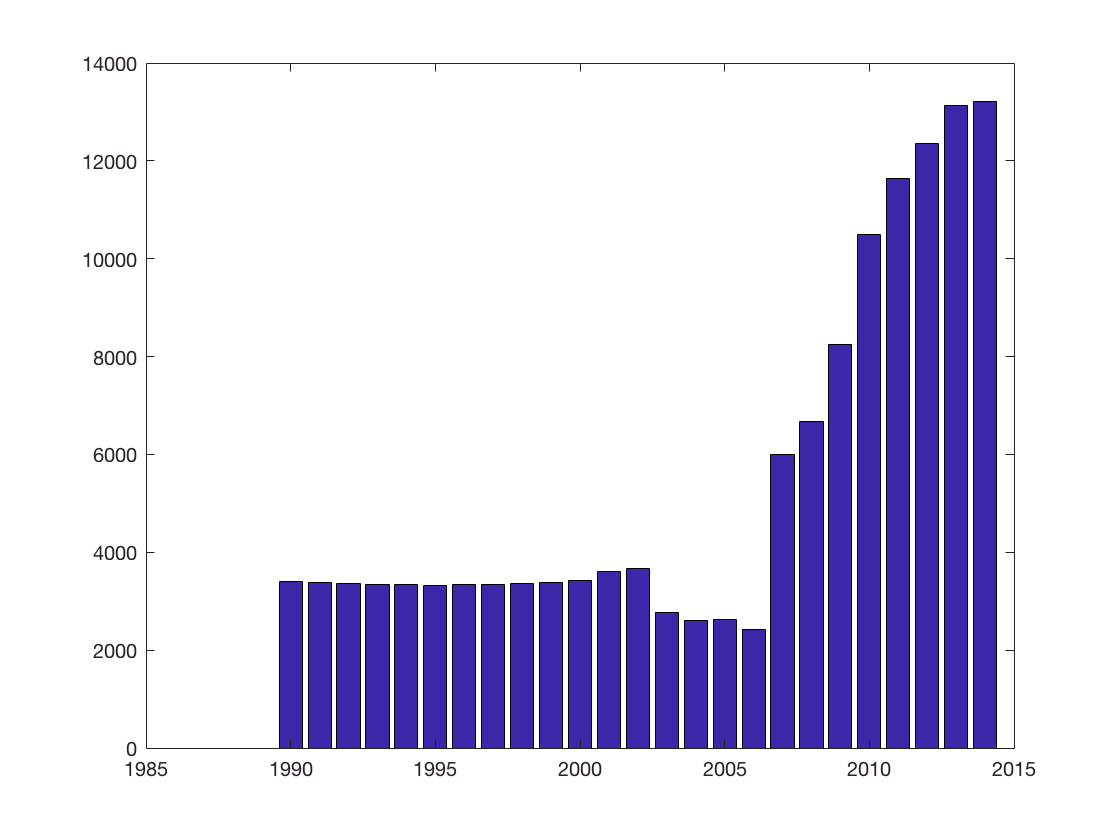

b1 = bar(year, australia_qty);

ax1 = fig1.CurrentAxes();

## Modify axis properties

Add axis labels, and modify axis properties

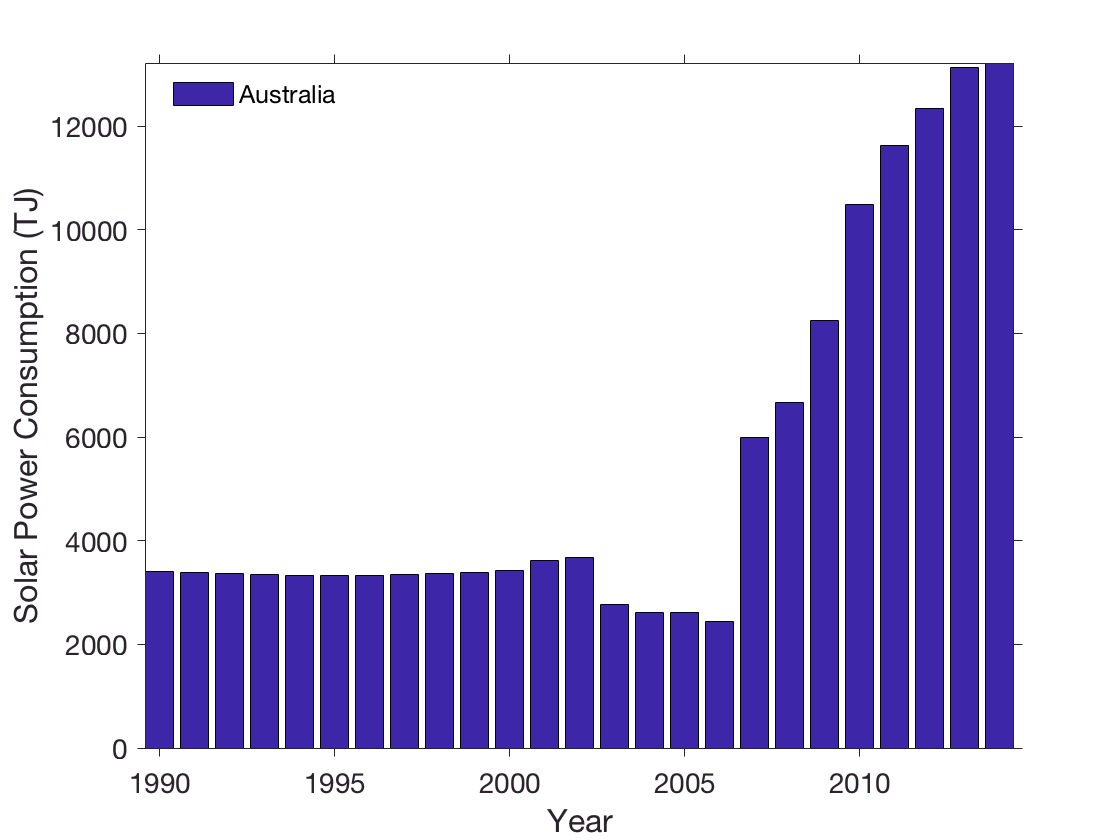

ax1.FontSize = 14;
ax1.TickDir = 'out';
ax1.XLabel.String = 'Year';
ax1.XLabel.FontSize = 16;
ax1.YLabel.String = 'Solar Power Consumption (TJ)';
ax1.YLabel.FontSize = 16;
axis tight;
legend('Australia', 'Location', 'best')
legend('boxoff');

## Add additional data

Add bars for Denmark and France data. By default, the bars are grouped.

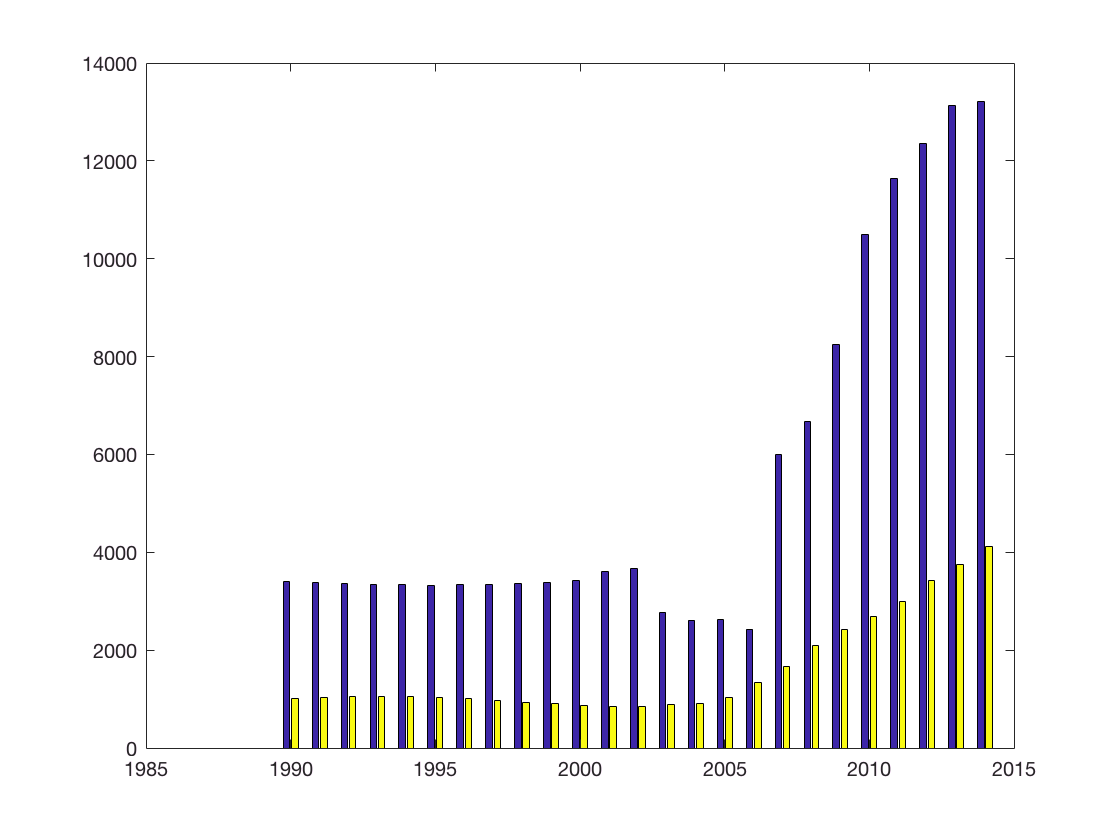

b1 = bar(year, [australia_qty france_qty]);

## Modify axis and bar properties

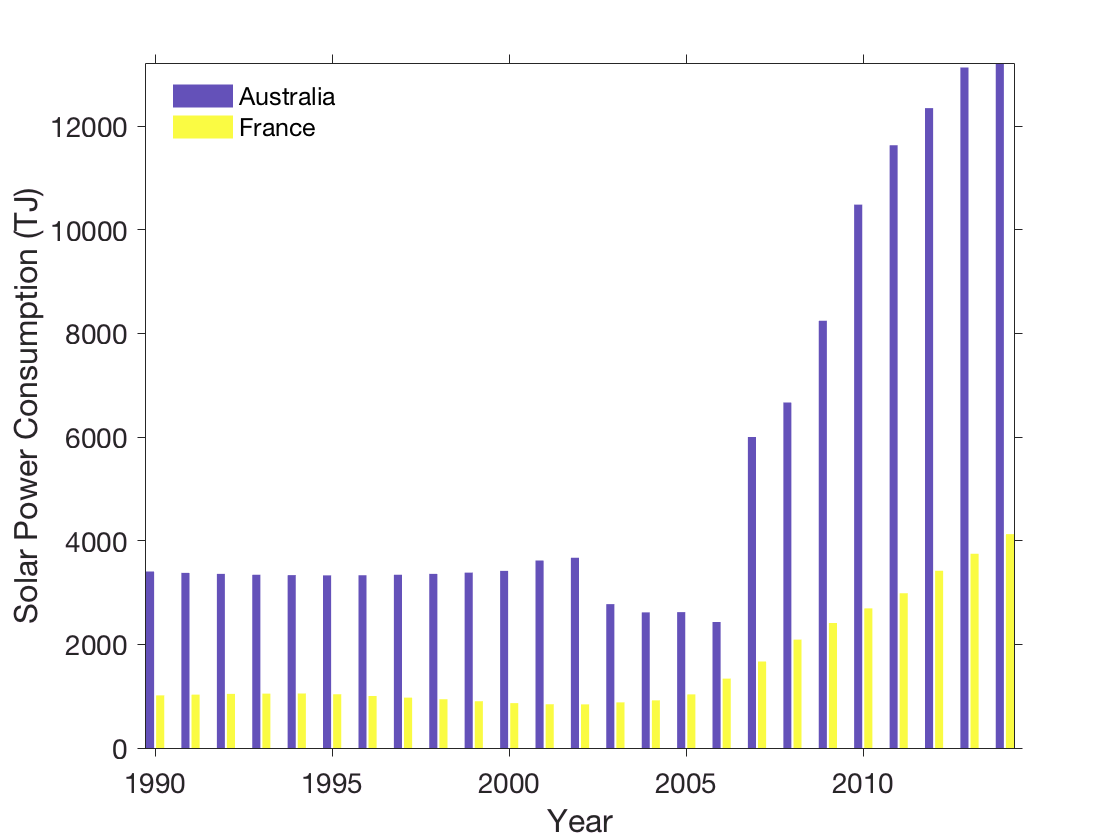

ax1.FontSize = 14;
ax1.TickDir = 'out';
ax1.XLabel.String = 'Year';
ax1.XLabel.FontSize = 16;
ax1.YLabel.String = 'Solar Power Consumption (TJ)';
ax1.YLabel.FontSize = 16;
axis tight;
legend('Australia', 'France', 'Location', 'best')
legend('boxoff');
b1(1).LineStyle = 'none';
b1(2).LineStyle = 'none';
b1(1).FaceAlpha = 0.8;
b1(2).FaceAlpha = 0.8;

## Add more data

Add bars for data from all remaining countries

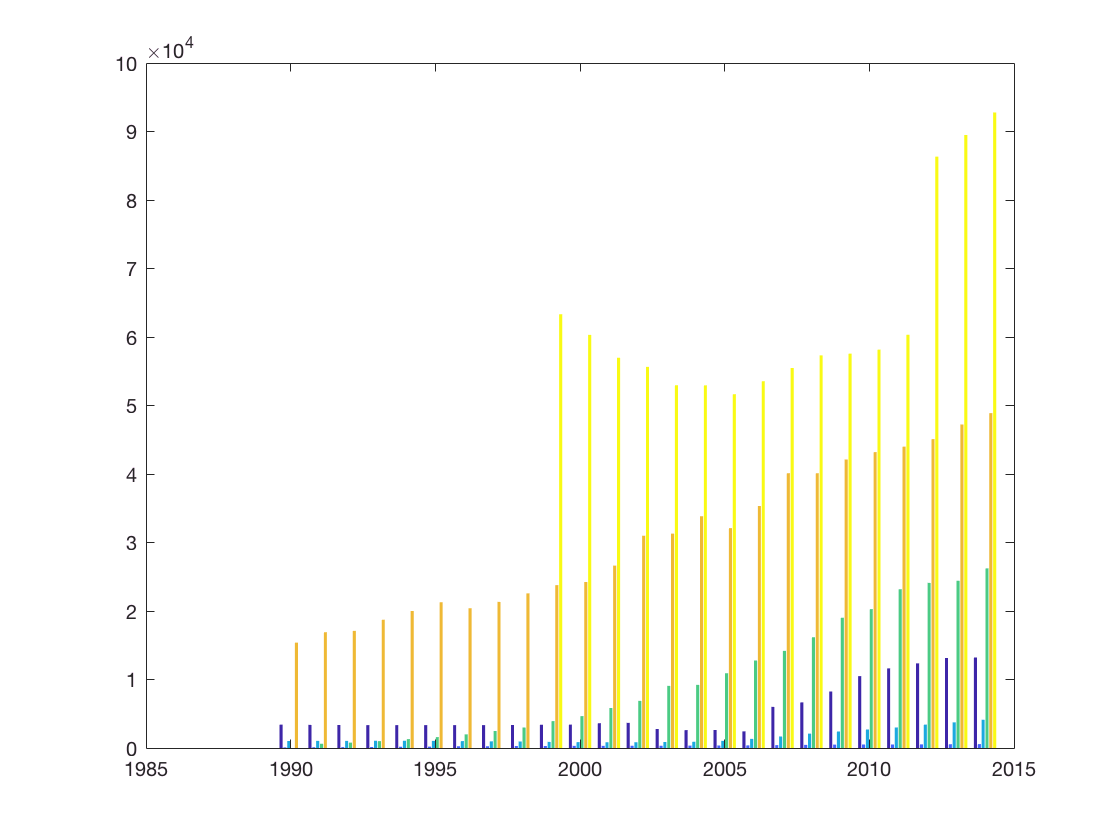

b1 = bar(year, [australia_qty denmark_qty france_qty germany_qty japan_qty usa_qty],...
    'LineStyle', 'none');

## Modify axis properties

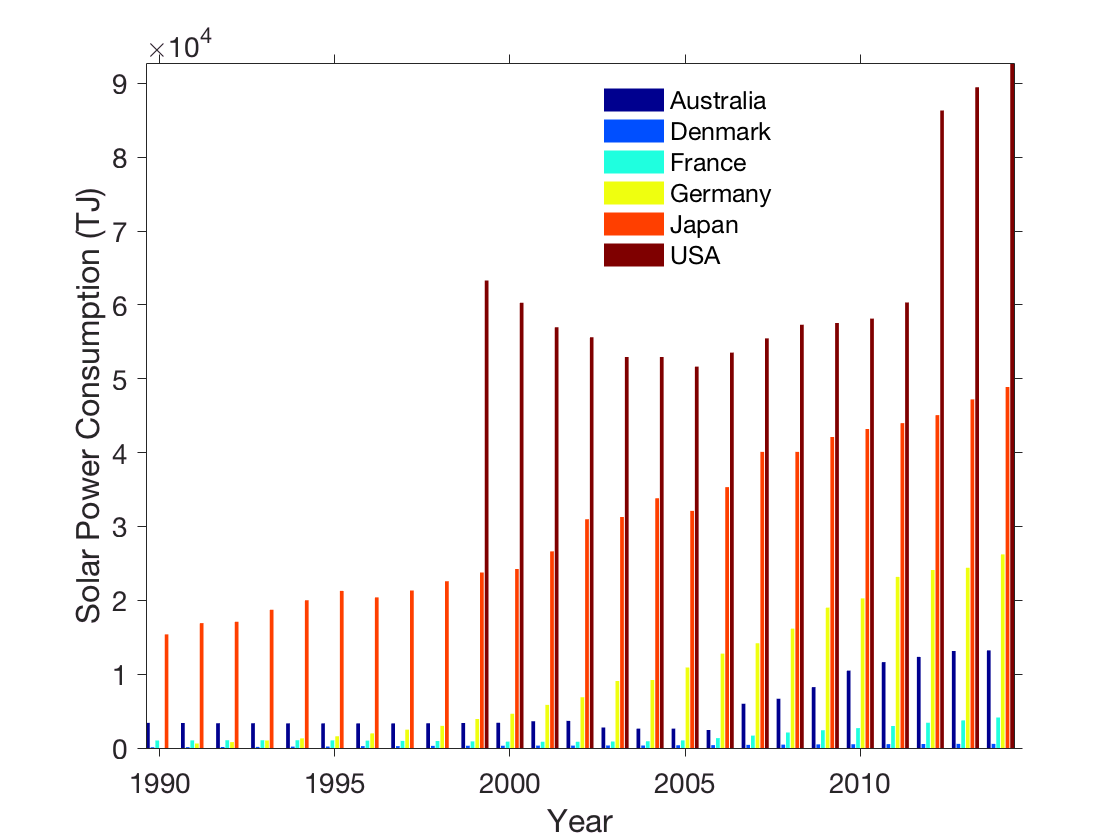

ax1.FontSize = 14;
ax1.TickDir = 'out';
ax1.XLabel.String = 'Year';
ax1.XLabel.FontSize = 16;
ax1.YLabel.String = 'Solar Power Consumption (TJ)';
ax1.YLabel.FontSize = 16;
axis tight;
legend('Australia', 'Denmark', 'France', 'Germany', 'Japan', 'USA', 'Location', 'best')
legend('boxoff');
colormap('jet');

## Stacked bar chart

Convert to a percentage amount and plot a stacked bar chart

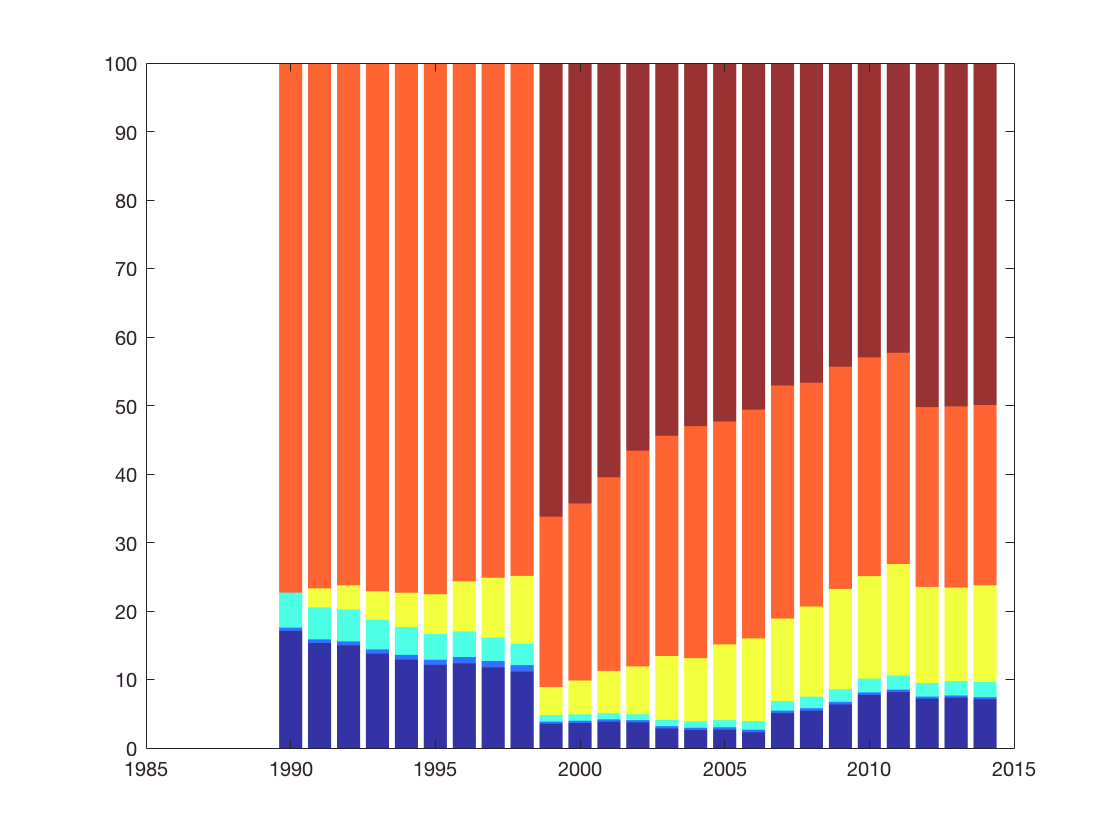

australiap = (australia_qty ./ total_qty) * 100;
denmarkp = (denmark_qty ./ total_qty) * 100;
francep = (france_qty ./ total_qty) * 100;
germanyp = (germany_qty ./ total_qty) * 100;
japanp = (japan_qty ./ total_qty) * 100;
usap = (usa_qty ./ total_qty) * 100;
b1 = bar(year, [australiap denmarkp francep germanyp japanp usap], ...
    'stacked', 'LineStyle', 'none', 'FaceAlpha', 0.8);

## Modify axis properties

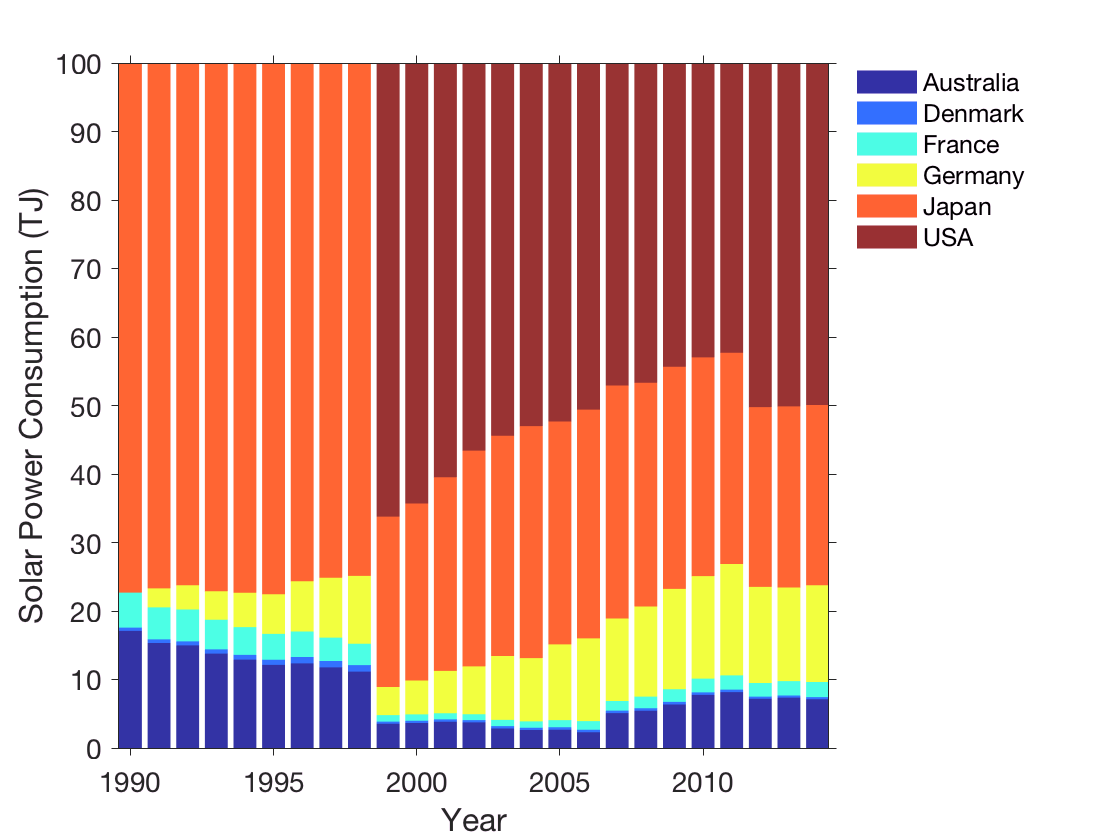

ax1.FontSize = 14;
ax1.TickDir = 'out';
ax1.XLabel.String = 'Year';
ax1.XLabel.FontSize = 16;
ax1.YLabel.String = 'Solar Power Consumption (TJ)';
ax1.YLabel.FontSize = 16;
axis tight;
legend('Australia', 'Denmark', 'France', 'Germany', 'Japan', 'USA', 'Location', 'bestoutside')
legend('boxoff');